# Model spread of virus with testing- Dynamic False Negative, Fast Spread

## Set Up Semester

%Total Number of Students
studnum = 10000;

%Struct to keep track of each student's health for each iteration
students(studnum) = struct('healthy', [], 'sick', [], 'recovered', [], 'progression', [], ...
'symptomatic', [], 'mild', [], 'severe', [], 'detectable', [], 'r0', [], 'sympstartday', [], ...
'viralload', [], 'iso', [], 'spreadfrom', [], 'spreadto', [],'transattempt', []);

% Semester Length: 120 days
day = (1:1:120);

## Probability of recovery

% median time to recovery is 2 weeks for mild and 3-6 weeks for severe
% (21-42 days)
recdays = 1:1:42+14;

mildrec = makedist('Binomial',"N",42,"p", 14/42); 
sevrec=makedist('Binomial', "N",42,"p", ((21+21+42)/3)/42);

## Probability of spread

% Make a distribution of transmissibility with a mean equal to R0;

R0 = 2.6; % Setting the R0 to 2.6 makes the Apparent R 2.5
rnstd = .1; %std deviation for the distribution

rnaughtpdf = makedist('Normal', "mu",R0, "sigma",rnstd);
rnaughtpdf = truncate(rnaughtpdf, 0, 35); % truncate at 0
rnots = 0:0.1:10;

## Time to Symptom and Viral Load

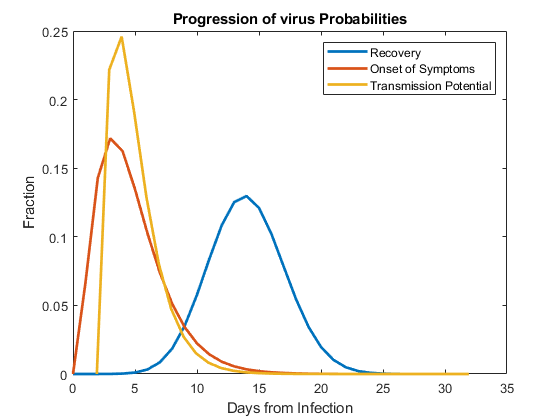

%Load profile of the viral shedding from He et al
load('infection_param_He_et_al.mat');

%Load profile of the false negative rate from Kucirka et al
load('kucirkaposrate_falseneg.mat')

% Plot disease progression probabilities
diseasedays = 0:1:30;
figure()
plot(diseasedays, pdf(mildrec, diseasedays), "LineWidth",2); %mild recovery
hold on
plot(diseasedays, pdf(incdis, diseasedays), "LineWidth",2); %symptom onset
plot(diseasedays + median(incdis) -2.3, pdf(virdis, diseasedays), "LineWidth",2) %Tranmission potential
legend('Recovery', 'Onset of Symptoms', 'Transmission Potential');
title('Progression of virus Probabilities');
xlabel('Days from Infection');
ylabel("Fraction");


% use recdays as base time line, but one shorter for offset
stdviralload =pdf(virdis, recdays);

%normalize to sum to 1 so it can be scaled by the R0
stdviralload = stdviralload./sum(stdviralload);

## Testing and Preventative Measures

%Chance of False Negative
testerror =  [negextended, ones(1,size(recdays,2)-size(negextended,2))]; % false negative rate- PERFECT=0

%Cell array to keep track of positive and negative tests
tests = [];

% Determines if the whole student body is tested on the first day
firstdaytest = 0;

%Determines if the university tests the students
dotest = 0;

%Determines if at any point the whole student body is tested 
% at any point mid-semester
testbolus = 0;

%%Contact tracing
% Contacttracing and diseasecontrol Ken T. D. Eames1and Matt J. Keeling  
% Contact Tracing must reach efficientcy of 1 - (1/R0)
% to suceed

%Determines if contact tracing is implimented for the university
ContactTracing = 1;

%The efficiency of the contact tracing
ContactTracingEff = 0.75;

% Record tests used for contact tracing
cttests = cell(iterationsize,1);
for i = 1:iterationsize
    cttests{i,1} = zeros(day(1,end), 1);
end

% Record Known Cases
kncases = [];
kncases = zeros(day(1,end), iterationsize);

%%Symptoms and Severity
% CDC describes 81% mild to moderate, 14% severe, 5% critical. 
% This is presumably among the symtomatic population.  Based on the navy
% ship data (350/600 according to NavyTimes), ~ 50% may be asymptomatic.
% should decrease the remaining cases accordingly, lump severe and
% critical, should be equivalent for our purposes (i.e., in medical care)

%Percentage of the population showing symptoms 
% such as none, mild and severe
asymptomatic = 0.5;
mild = 0.81*(1-asymptomatic);
severe = 1-asymptomatic-mild;

% Self Isolation due to symptoms/ Healthcare
% mild self isolation probability
mildiso = 0;

% severe self isolation probability
severeiso = 0;

%%Masking
% van der Sande et al: 1/2.95 effect on transmission to person wearing a
% home made mask.  thus mask are 67% effective at blocking particulates,
% 33% gets through
%Chu et al 2020: Found aOR 0.33 (95%CI 0.17-0.61) from wearing a surgical
%mask vs no face mask
maskfactor= 0.33

maskfactor = 0.3300


%If students are wearing Masks or not
masking = 0;

%Percentage of students who comply with face masks
maskingprob = 0.8;


## Initialize Healthy and Sick Students

%sidx serves as a cell array of each iteration's student health daily
% 1 = healthy, 2 = sick, 3 = recovered
sidx = []; 
for r = 1:iterationsize;
    %Set Every Student to Healthy at Every TimePoint In Every Iteration
    sidx{r,1} = ones(studnum, day(end)); 
    
    %Set Every Student to Not Tested/ Healthy at Every TimePoint In Every Iteration
    tests{r,1} = zeros(studnum, day(end));
end

%%For Each Iteration of Each Simulation
for r = 1:iterationsize;
    
    % Intialize students struct
    for i = 1:studnum;
        %Intialize Every Student as Healthy
        students(i).healthy = 1;
        students(i).recovered = 0;
        students(i).sick = 0;
        students(i).progression =0;
        students(i).symptomatic = 0;
        students(i).mild = 0;
        students(i).severe = 0;
        students(i).detectable = 0;
        students(i).asymptomatic = 0;
        students(i).viralload = zeros(1,size(recdays,2));
        students(i).iso = 0;
        students(i).spreadfrom=[];
        students(i).spreadto=[];
        students(i).transattempt=0;
        %If The Student Is Wearing Masks
        if masking == 1 & rand(1) < maskingprob; 
            
            %Scale the Individual's Transmission by the Masking's Efficacy
           students(i).r0 = random(rnaughtpdf)*maskfactor; 
        
        %If the Student isn't wearing a Mask
        else 
            
            %The Student will have full Tranmissionability
            students(i).r0 = random(rnaughtpdf); 
        end
    end
    
%%Initialize sick
%Percent of Student Population That Will Start The Semester As Sick
percentsick = 0.1; 
numsick = floor(percentsick/100*studnum);

%Randomly Choose the Sick Students
startsick = randperm(studnum, [numsick]);

%For Each Initially Sick Student
for i = 1:size(startsick,2);
    
    %Set Each Inital Sick Student As Sick
    students(startsick(i)).sick = 1;
    students(startsick(i)).healthy = 0;
    sidx{r, 1}(startsick(i),1) = 2;
    
    %Set Initial Sick Students to have gotten sick from themselves 
    %since there isn't an entity in the model responsible for them
    students(startsick(i)).spreadfrom = startsick(i); 
    
    %Set Initial Sick Students at random stage of progression  
    students(startsick(i)).progression = randperm(14,1);
    
    %Randomly choose severity of symptoms for each Initial Sick Student
    symprand = rand(1);
    if symprand < asymptomatic;
        %Student's Symptoms are Asymptomatic
        students(startsick(i)).asymptomatic = 1;
        
    elseif symprand < asymptomatic + mild;
        %Student's Symptoms are Mild
        students(startsick(i)).mild = 1;
        
    else
        %Student's Symptoms are Severe
        students(startsick(i)).severe = 1;  
    end
    
    % Determine day symptoms start
    students(startsick(i)).sympstartday = ceil(random(incdis));
  
    %Determine Viral Load Distribution Based on Symptom Start Day
    
    %If Symptoms Start Pretty Much Immediately Upon Infection then
    % the Viral Load Starts Immediately
    if students(startsick(i)).sympstartday < 3;
        students(startsick(i)).viralload(2:end) = stdviralload(1:end-1);
        
    %Otherwise, the Viral Load determined by the Symptom Start Day (-2)
    else
         students(startsick(i)).viralload(students(startsick(i)).sympstartday-2:end) = ....
              stdviralload(1:end-students(startsick(i)).sympstartday+3);
    end
    
     %Offset is used to determine if the virus is detectable based on
     %kuricka's false negative rate 
     offset=(students(startsick(i)).progression-students(startsick(i)).sympstartday);                  
     
     %If it's in the range of kucirka's data
     if offset < 29 && offset>-6
         
           %Decide based on probability if the virus is detectable or not
           if negextended(offset+6)<rand(1)
                students(startsick(i)).detectable = 1; 
           else
                students(startsick(i)).detectable = 0;
           end
     %If it isn't in the range the virus isn't detectable
     else
          students(startsick(i)).detectable = 0;
     end
end
studentseachday(1)={students};

%% Test the entire student body the first day (if firstdaytest is turned on)
if firstdaytest == 1;
    for s = 1:studnum;
        %If Student's viral load is detectable
        if students(s).detectable == 1;
            %If the Test doesn't give a false positive based on kucirka's
            %false negative rate
            if rand(1) > testerror((students(s).progression-students(s).sympstartday)+6);
                
                % Label Test as Positive for Covid-19
                tests{r,1}(s,1) = 1;
                kncases(1,r) = kncases(1,r) +1;
                
                %The Student isolates
                students(s).iso = 1;
            end
        end
    end
end

## Start Simulation of the Semester


% steps per day: 
% (1) identify who is sick, healthy, recovered, 
% (2) if sick, spread disease from sick people 
% (3) if sick, determine who gets better
% (4) do testing

%For each day in the semester
for i = 2:size(day,2)
    % find out who is sick, healthy,
    
    % If testbolus is turned on, the whole student body is tested
    if any(testbolus == i);
    for s = 1:studnum;
       %If Student's viral load is detectable
        if students(s).detectable == 1;
            %If the Test doesn't give a false positive
            if rand(1) > testerror((students(s).progression-students(s).sympstartday)+6);;
                
                % Label Test as Positive for Covid-19
                tests{r,1}(s,1) = 1;
                kncases(1,r) = kncases(1,r) +1;
                
                %The Student isolates
                students(s).iso = 1;
            end
        end
    end
    end
    
    %For Each Student
    for s = 1:studnum
        %If the student has recovered
        if students(s).recovered ==1;
            
            %Label that student as Recovered in the sidx so they can't be
            %infected again
            sidx{r,1}(s,i) = 3;
        end
        
        %If the student is sick
        if students(s).sick == 1;
            
            % record sick status and advance progression
            sidx{r,1}(s,i) = 2;
            
            % iterate progression
            students(s).progression = students(s).progression + 1; 
            
                 %Offset is used to determine if the virus is detectable based on
             %kuricka's false negative rate 
             offset=(students(s).progression-students(s).sympstartday);                  
             
             %If it's in the range of kucirka's data
             if offset < 29 && offset>-6
                 
                   %Decide based on probability if the virus is detectable or not
                   if negextended(offset+6)<rand(1)
                        students(s).detectable = 1; 
                   else
                        students(s).detectable = 0;
                   end
                   
             %If it isn't in the range the virus isn't detectable
             else
                  students(s).detectable = 0;
             end
            
            % check if they isolate themselves based on symptoms
            %If the student has symptoms
            if students(s).asymptomatic ~= 1;
                %If symptoms have started for a mildly sick student
                if students(s).mild == 1 && students(s).progression >=...
                        students(s).sympstartday
                    
                    %If they isolate
                    if rand(1) < mildiso
                        students(s).iso = 1; %label them as isolated
                        kncases(i,r) = kncases(i,r) +1;
                         
                        % Contact Tracing upon finding sick person
                        if ContactTracing == 1;
                            
                            %If Contact Tracing Works
                            if rand(1) < ContactTracingEff
                                % find who they got it from
                                students(students(s).spreadfrom).iso = 1; 
                                 cttests{r,1}(i,1) = cttests{r,1}(i,1) + 1;
                                 
                                 % Add them to known cases
                                 kncases(i,r) = kncases(i,r) +1;
                                 
                            end
                            
                            %For each student that student spread the
                            %infection to
                            for j = 1:size(students(s).spreadto, 1);
                                 %If Contact Tracing Works
                                if rand(1) < ContactTracingEff;
                                     % find who they got it from
                                     students(students(s).spreadto(j)).iso = 1; 
                                     cttests{r,1}(i,1) = cttests{r,1}(i,1) + 1;
                                 
                                     % Add them to known cases
                                     kncases(i,r) = kncases(i,r) +1;
                                end
                            end
                        end
                    end
                    
                %If symptoms have started for a severely sick student
                elseif students(s).severe == 1 & students(s).progression >= ...
                        students(s).sympstartday;
                    
                    %If they isolate
                    if rand(1) < severeiso;
                        students(s).iso = 1; %label them as isolated
                        kncases(i,r) = kncases(i,r) +1;
                        
                        % Contact Tracing upon finding sick student
                        if ContactTracing == 1;
                            if rand(1) < ContactTracingEff;
                            students(students(s).spreadfrom).iso = 1;
                            cttests{r,1}(i,1) = cttests{r,1}(i,1) + 1;
                            kncases(i,r) = kncases(i,r) +1;
                            end
                            
                            %For each student that student spread the
                            %infection to
                            for j = 1:size(students(s).spreadto, 1);
                                %If Contact Tracing Works
                                if rand(1) < ContactTracingEff;
                                % find who they got it from
                                students(students(s).spreadto(j)).iso = 1;
                                cttests{r,1}(i,1) = cttests{r,1}(i,1)+1;
                                
                                % Add them to known cases
                                kncases(i,r) = kncases(i,r) +1;
                                end
                                
                            end
                            
                        end
                    end
                end
                
            end
            
            % Sick Student infecting others based on their viral load
            if students(s).iso ~=1;
                
                %Determine if they are going to infect a new person based
                %on their viral load on that progression day and the R0
                if rand(1) < (students(s).r0 * students(s).viralload(1,students(s).progression))
                    
                    % figure out which student is going to be infected
                    newsick = randi(studnum);
                    
                    %record the transmission attempt in order to calculate
                    %apparent R
                    students(s).transattempt=students(s).transattempt+1;
                    
                    %If the person who is supposed to be infected next is
                    %sick or recovered
                    if students(newsick).sick == 1 | students(newsick).recovered ==1;
                        
                        %Nothing happens
                        
                    else
                        % initialize sick conditions for newly infected student
                        students(newsick).sick = 1;
                        sidx{r,1}(newsick,i) = 2;
                        students(newsick).healthy = 0;
                        students(newsick).progression = 1;
                        
                        % Who did the student give it to
                        students(s).spreadto = [students(s).spreadto, newsick]; 
                        
                        % Who did newsick student get it from?
                        students(newsick).spreadfrom = s; 
                        
                        % Determine day symptoms start for newsick
                        students(newsick).sympstartday = ceil(random(incdis));
                        
                        
                            %Determine Viral Load Distribution Based on Symptom Start Day
    
                        %If Symptoms Start Pretty Much Immediately Upon Infection then
                        % the Viral Load Starts Immediately
                        if students(newsick).sympstartday < 3;
                            students(newsick).viralload(2:end) = stdviralload(1:end-1);
                            
                        %Otherwise, the Viral Load determined by the Symptom Start Day (-2)
                        else
                            students(newsick).viralload(students(newsick).sympstartday-2:end) =...
                                stdviralload(1:end-students(newsick).sympstartday+3);
                        end
                        
                        %Randomly choose severity of symptoms for each Initial Sick Student
                        symprand = rand(1);
                        if symprand < asymptomatic;
                            %Student's Symptoms are Asymptomatic
                            students(newsick).asymptomatic = 1;
                            
                        elseif symprand < asymptomatic + mild;
                            %Student's Symptoms are Mild
                            students(newsick).mild = 1;
                            
                        else
                            %Student's Symptoms are Severe
                            students(newsick).severe = 1;  
                        end
                    end
                 
                end
            end

            % Check if the sick student recovers
            % If the student is sick and the infection progression is past
            % the symptom start
            if students(s).sick == 1 &  students(s).progression > students(s).sympstartday
                
                %Recovery is based on the cumulative distribution function
                if rand(1) < cdf(mildrec, students(s).progression-students(s).sympstartday)
                    
                    % Label as recovered
                    students(s).recovered = 1;
                    students(s).sick = 0;
                    students(s).detectable = 0;
                    sidx{r,1}(s,i) = 3;
                end
            end
        end
    end
    
    % Test students, no delay on results, with false negative
    if dotest == 1;
        
        %If it is a day of testing (based on testfreq)
        if mod(i,testfreq) == 0;
            
            %Randomly choose which students get tested
            stotest = randperm(studnum, numtest);
            
            %For each student who is being tested
            for j = 1:numtest
                
                %if that student is detectable
                if students(stotest(j)).detectable == 1;
                    
                    %And if it isn't a false negative
                    if rand(1) > testerror;
                        
                        %The student isolates and another case is known in
                        %the university
                        students(stotest(j)).iso = 1;
                        tests{r,1}(stotest(j),i) = 1;
                        kncases(i,r) = kncases(i,r) +1;
                        
                        % Contact Tracing upon finding sick student
                        if ContactTracing == 1;
                            %Based on the efficiency of the contact tracing
                            if rand(1) < ContactTracingEff
                                
                                %Found person who infected them and
                                %isolate them
                                students(students(stotest(j)).spreadfrom).iso = 1; 
                                cttests{r,1}(i,1) = cttests{r,1}(i,1)+1;
                                kncases(i,r) = kncases(i,r) +1;       
                            end
                            
                            %For each person the sick person spread it to
                            for x = 1:size(students(stotest(j)).spreadto, 1)
                                
                                % Based on the efficiency of the contact tracing                                
                                if rand(1) < ContactTracingEff;
                                    
                                    % Found people they infect and isolate
                                    % them
                                    students(students(stotest(j)).spreadto(x)).iso = 1; 
                                    cttests{r,1}(i,1) = cttests{r,1}(i,1)+1;
                                    kncases(i,r) = kncases(i,r) +1;
                                end
                            end
                        
                        end
                    % If the virus is detectable but test is negative
                    % (false negative)
                    else 
                        tests{r,1}(stotest(j),i)=2;
                    end
                
                % If the student is sick but undetectable
                elseif students(stotest(j)).sick == 1
                     tests{r,1}(stotest(j),i)=2;
                end
            end
        end
    end
end 
    %save transmission attempts
   transattempt_all(:,r)=transpose({students.transattempt});
   
end

## Graph of Apparent R0

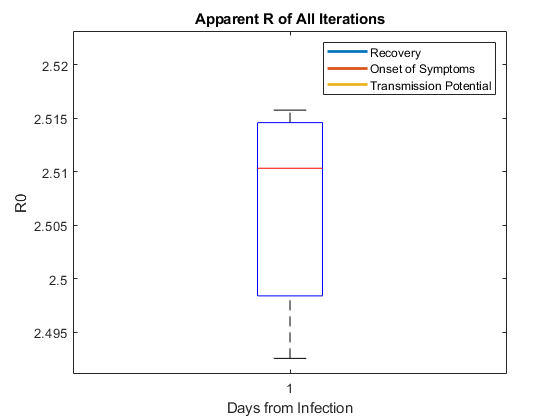

%For each iteration, calculate the apparent R0 of covid-19
for r = 1:iterationsize
    
     %From sidx, determine who is sick or has been sick throughout the
     %semester
     spreaders=(sidx{r,1}(:,end)==2)+(sidx{r,1}(:,end)==3);
     
     %For each person who was/is sick, 
     % determine how many people they infected
     spreadto= cell2mat(transattempt_all((spreaders==1),r));
     
     %Find the average number of people infected per person
     spreadees=mean([spreadto]);
     
     %Save in array of all Apparent R0s
     r0sample(r,1)=spreadees;
end

    %Create a boxplot of the Apparent R0s
    boxplot(r0sample) 
    title('Apparent R of All Iterations' )
    ylabel('R0')